clc; clear all; close all;

img_path = fullfile('Codes','OD_zoom_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

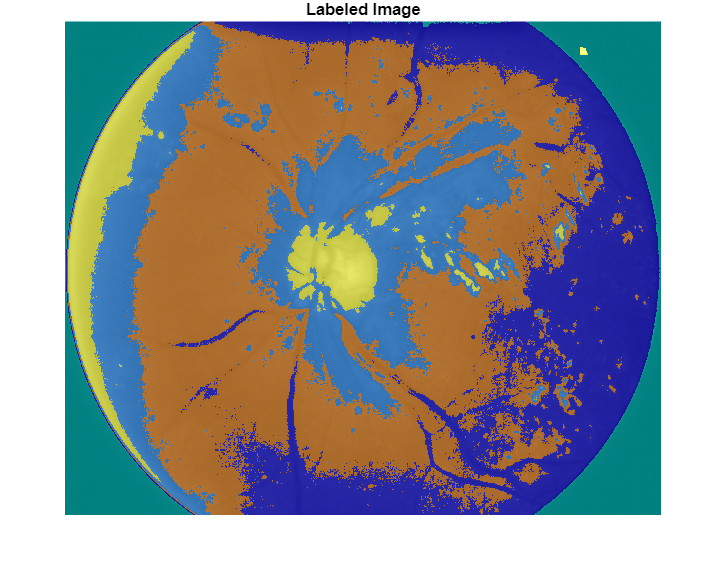

RGB = imread(string(fullfile(img_path, T{52,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
maxR=max(R(:));
maxG=max(G(:));
maxB=max(B(:)); 

I=G;

[L,Centers] = imsegkmeans(I,5);
B = labeloverlay(I,L);
imshow(B)
title("Labeled Image")